# **IO3xx Digital - Loopback**

This example demonstrates how to use the digital input and output lines, which are both on the same I/O module. You can test the basic functionality of the digital I/O lines by running this loopback.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **8 x DIO channel**

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, data is sent from the digital output channels to the digital input channels. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used.

In the pin mapping of your configuration file, locate the functionalities specified in the table below. Connect the corresponding pins on the terminal board with jumper wires.

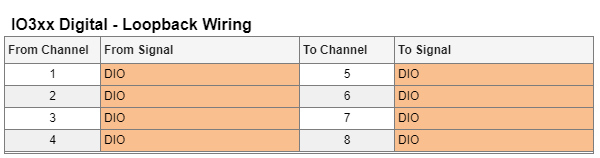

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Digital_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

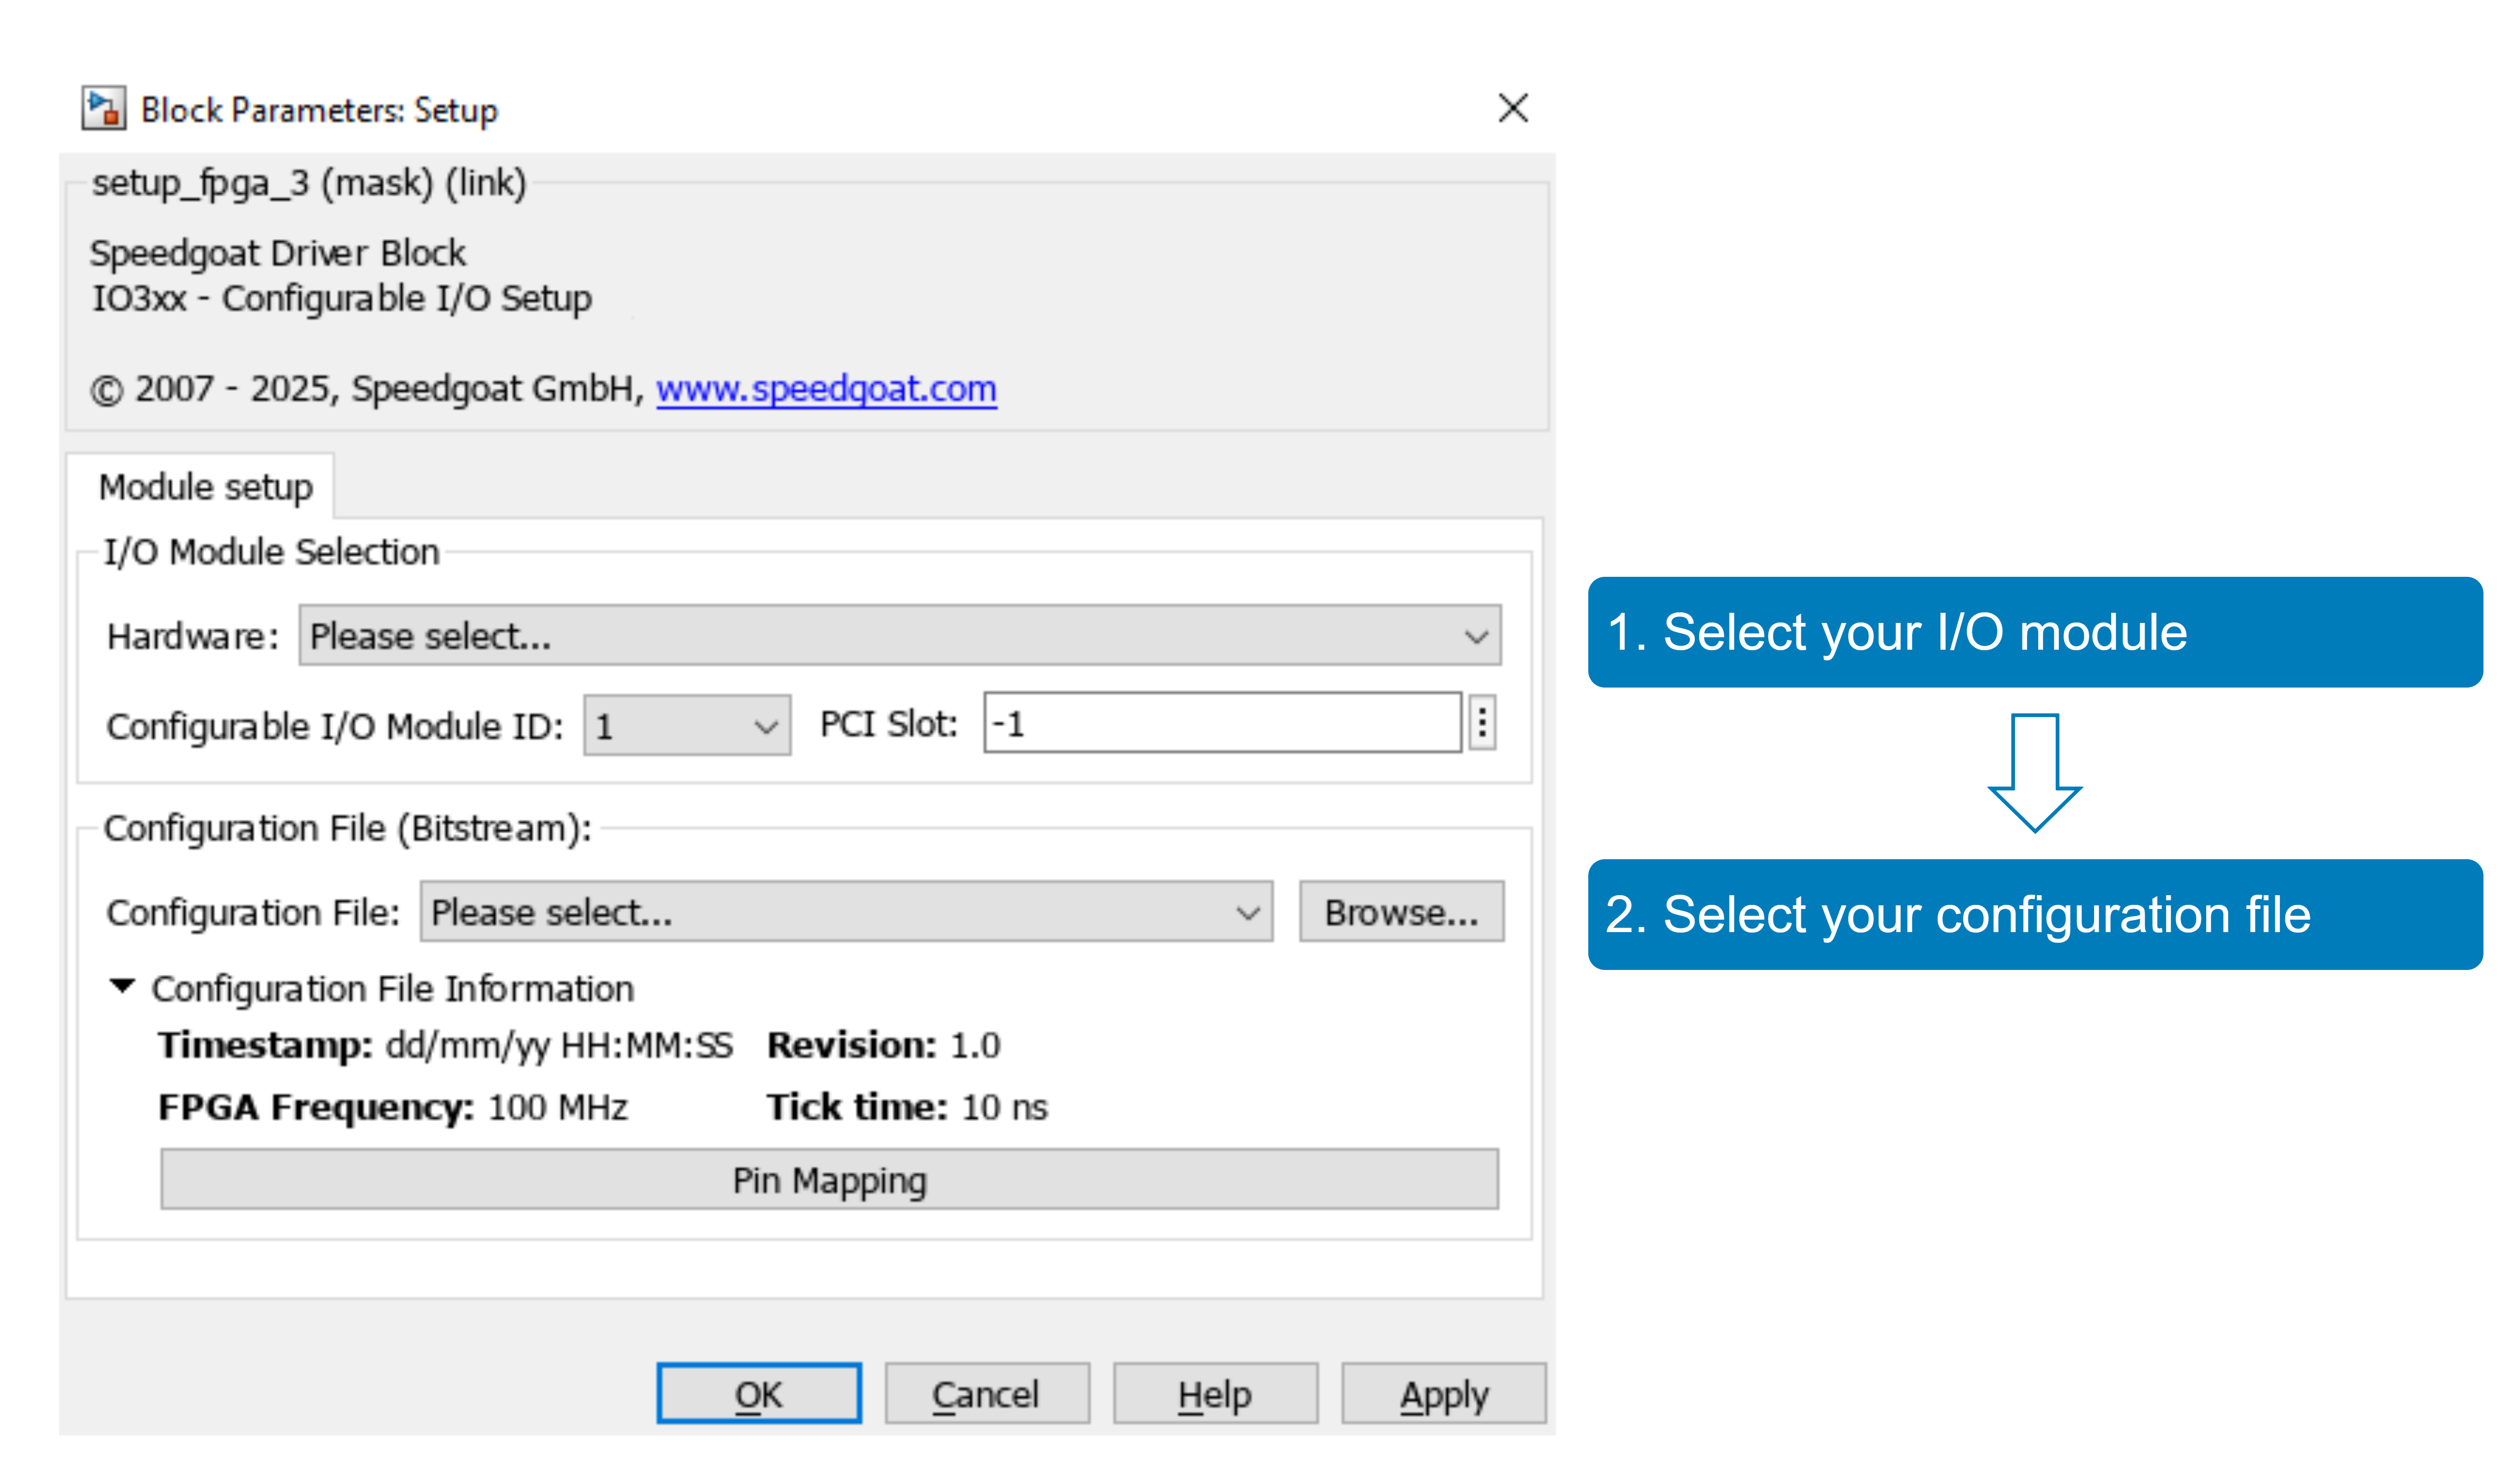

With the **Pin Mapping** button you can now check where the functionalities are located.

### Model Description

In the model, periodic pulses are generated on the Digital output channels and then received on the Digital input channels. We add to each measured signal a different offset to better see them in the Scope block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(gcs, 'SimulationMode', 'external'); % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect'); % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10);
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope. The digital input signals must be displayed as in the picture below (time axis is zoomed in):

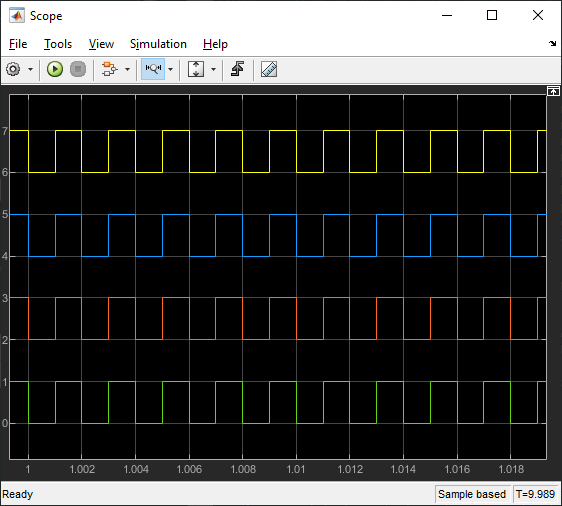

## Additional References

- [IO3xx Digital - documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_digital)